clear; clc; close all;

%% 1. DEFINITIONS AND DATA LOADING

%  Mapping of experiments 
experiments = {
    'sx100',   100, 1; 'dx200',   200, 2; 'sx200',   200, 1; 'dx400',   400, 2; 'sx400',   400, 1;
    'dx600',   600, 2; 'sx600',   600, 1; 'dx800',   800, 2; 'sx800',   800, 1; 'dx1000',  1000, 2;
    'sx1000',  1000, 1; 'sx1200',  1200, 1; 'sx1400',  1400, 1; 'dx2000',  2000, 2; 'sx2000',  2000, 1;
    'vtc200',  200, 3; 'vtc400',  400, 3; 'vtc600',  600, 3; 'vtc800',  800, 3; 'vtc1000', 1000, 3; 'vtc2000', 2000, 3
};

%  Load the data matrices 
try
    experimental_data = load('datipesi.mat');
    fprintf('Data file "datipesi.mat" successfully loaded.\n');
catch ME
    error('Error: Unable to load file "datipesi.mat". Details: %s', ME.message);
end

Data file "datipesi.mat" successfully loaded.


%2. EXTRACTION AND COMPUTATION OF MEANS (for all data)

num_experiments = size(experiments, 1);
varTypes = {'string', 'double', 'double', 'double', 'double', 'double'};
varNames = {'MatrixName', 'Load_g', 'LoadedSensor', 'Mean_Vsx', 'Mean_Vdx', 'Mean_Vvtc'};
all_results = table('Size', [num_experiments, 6], 'VariableTypes', varTypes, 'VariableNames', varNames);

for i = 1:num_experiments
    matrix_name = experiments{i, 1};
    raw_data = experimental_data.(matrix_name);
    
    if istable(raw_data); data_matrix = table2array(raw_data);
    else; data_matrix = raw_data; end
    
    clean_data_matrix = data_matrix(all(~isnan(data_matrix) & isreal(data_matrix), 2), :);
    
    if isempty(clean_data_matrix); continue; end
    
    means = mean(clean_data_matrix, 1);
    
    all_results(i, :) = {matrix_name, experiments{i, 2}, experiments{i, 3}, means(3), means(2), means(1)};
end

all_results = rmmissing(all_results, 1);
disp('Table with the mean values of all measurements:');

Table with the mean values of all measurements:


disp(all_results);

    MatrixName    Load_g    LoadedSensor    Mean_Vsx    Mean_Vdx    Mean_Vvtc
    __________    ______    ____________    ________    ________    _________

    "sx100"         100          1           1.9591      1.5692      1.6894  
    "dx200"         200          2           1.7405      1.6155      1.7027  
    "sx200"         200          1           1.8123      1.5735      1.6966  
    "dx400"         400          2           1.7373      1.6426      1.7098  
    "sx400"         400          1           1.8068      1.5619      1.6938  
    "dx600"         600          2           1.7202      1.6495      1.7171  
    "sx600"         600          1           1.9481      1.5527       1.724  
    "dx800"         800          2           1.7026      1.7668      1.7423  
    "sx800"    

% 3. TARGETED SELECTION, AGGREGATION, AND SAVING

%  DEFINE WHICH DATA TO USE 
selected_loads_g = [200, 400, 600, 800, 1000, 2000];
fprintf('\nTargeted selection of data for loads: %s g.\n', num2str(selected_loads_g));


Targeted selection of data for loads: 200   400   600   800  1000  2000 g.




sensors_map = {'Vsx', 'Vdx', 'Vvtc'};
data_for_modeling = struct();

for sensor_idx = 1:3
    % Select rows from the results table that correspond
    % both to the loaded sensor AND to the chosen loads.
    selection_idx = (all_results.LoadedSensor == sensor_idx) & ...
                    ismember(all_results.Load_g, selected_loads_g);
    
    selected_sensor_data = all_results(selection_idx, :);
    
    % Aggregate data (useful in case of multiple measurements for the same load)
    agg_data = groupsummary(selected_sensor_data, 'Load_g', 'mean', "Mean_" + sensors_map{sensor_idx});
    
    % Extract final vectors
    final_loads_g = agg_data.Load_g;
    final_voltages_V = agg_data.("mean_Mean_" + sensors_map{sensor_idx});
    
    % Save the cleaned data into a struct for the .mat file
    data_for_modeling.(("weights_g_" + sensors_map{sensor_idx})) = final_loads_g;
    data_for_modeling.(("voltages_V_" + sensors_map{sensor_idx})) = final_voltages_V;
end

% Save the struct in a new .mat file
output_file_name = 'dati_puliti.mat';
save(output_file_name, '-struct', 'data_for_modeling');
fprintf('\nCleaned and selected data successfully saved in: %s\n', output_file_name);


Cleaned and selected data successfully saved in: dati_puliti.mat


fprintf('This file contains only the data for the loads [400, 600, 800, 1000, 2000] g.\n');

This file contains only the data for the loads [400, 600, 800, 1000, 2000] g.


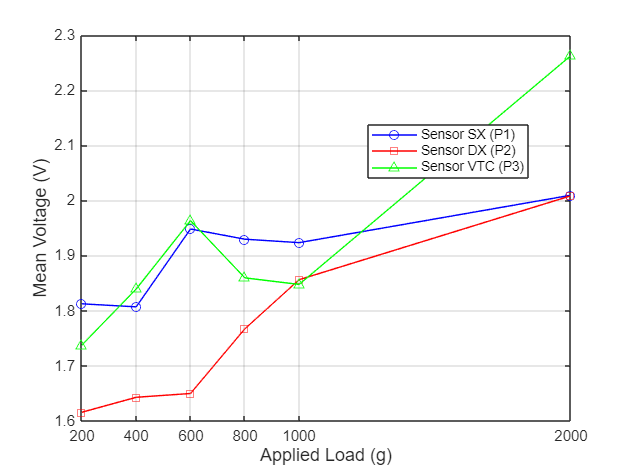


%% 4. (Optional) GRAPHICAL VISUALIZATION OF SELECTED DATA

figure('Name', 'Selected Calibration Data');
hold on; grid on; box on;
plot(data_for_modeling.weights_g_Vsx, data_for_modeling.voltages_V_Vsx, '-ob', 'DisplayName', 'Sensor SX (P1)');
plot(data_for_modeling.weights_g_Vdx, data_for_modeling.voltages_V_Vdx, '-sr', 'DisplayName', 'Sensor DX (P2)');
plot(data_for_modeling.weights_g_Vvtc, data_for_modeling.voltages_V_Vvtc, '-^g', 'DisplayName', 'Sensor VTC (P3)');
% title('Average Calibration Curves (Selected Data)', 'FontSize', 14);
xlabel('Applied Load (g)', 'FontSize', 12);
ylabel('Mean Voltage (V)', 'FontSize', 12);
legend('show', 'Location', 'best');
set(gca, 'XTick', selected_loads_g); % Show only the ticks of the chosen loads